# **Analysis of the Burgers equation by LSUN**

First run TanSacNet/code/setpath

Requirements: MATLAB R2022b 

Contact address: Shogo MURAMATSU, Faculty of Engineering, Niigata University, 8050 2-no-cho Ikarashi, Nishi-ku, Niigata, 950-2181, JAPAN http://msiplab.eng.niigata-u.ac.jp  

Copyright (c) 2023, Hayato Obara and Shogo MURAMATSU, All rights reserved.

clc, clear
close all


Parameters



nCoefs = 1; 
nDelay = 1;

pt = 2;
stride = 2*pt; % Stride (even)



Setting the conditions for the Burgers equation

mu = 1;                 % advection coefficient (fixed at 1)
nu = 0.05;              % Viscosity coefficient (corresponding to ν in the differential equation)
% Spatial Mesh
L_x = 10;               % Maximum value in space direction
dx = 0.1; 
N_x = floor(L_x/dx);    % Total number of meshes in spatial direction
X = linspace(0,L_x,N_x);% Coordinates
% Temporal Mesh
L_t = 10;               % Maximum value in time direction
dt = 0.1; 
N_t = floor(L_t/dt);    % Total number of meshes in time direction
T = linspace(0,L_t,N_t);% Coordinates
% Wave number discretization
k = 2*pi*fftfreq(N_x, dx);
% initial condition 
u0 = exp(-(X-3).^2/2); 
%u0 = np.sin(2*np.pi*X/L_x)
ndim = 100;

## **Data preparation**

%PDE resolution (ODE system resolution)
opt = odeset('MaxStep',5000);
[~,DataT] = ode45(@(t,u) burg_system(u,t,k,mu,nu),T,u0,opt);

## **Data visualisation**

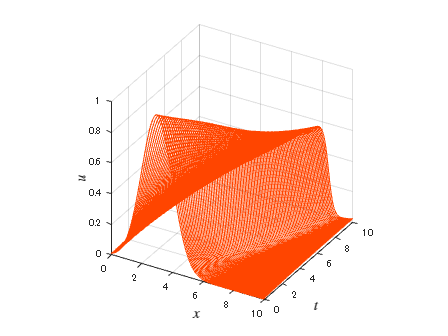

figure
orangered = [255 69 0]/255;
disp_plot3_(T,X,DataT,orangered)

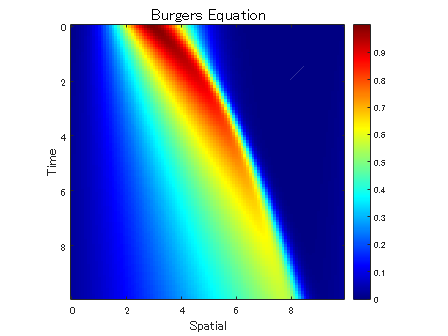


figure
disp_imagesc_(T,X,DataT)

## Configuration

Data size

nT = size(DataT,1);
nX = size(DataT,2);

Stride (block size)

assert(mod(nX,stride)==0,'stride must be a divisor of nX.');

Output dimension (per block)


assert(nCoefs<=stride,'nCoefs must be less than or equal to stride.')

Number of overlapping blocks (number of shifts)

nof = 1;
kx = 2*nof+1; % Number of overlapping blocks (odd)

## Setting display

strbuf = "-- Settings --" + newline;
strbuf = strbuf.append("Data size (space): " + num2str(nX) + newline);
strbuf = strbuf.append("Data size (time): " + num2str(nT) + newline);
strbuf = strbuf.append("Block size: " + num2str(stride) + newline);
strbuf = strbuf.append("Output dimension (per block): " + num2str(nCoefs) + newline);
strbuf = strbuf.append("Number of overlapping blocks: " + num2str(kx) + newline);
disp(strbuf)

-- Settings --
Data size (space): 100
Data size (time): 100
Block size: 4
Output dimension (per block): 1
Number of overlapping blocks: 3



### One-dimensional locally structured unitary networks (1-D LSUNs)

References.

-  Lu Gan and Kai-Kuang Ma, "On simplified order-one factorizations of paraunitary filterbanks," in  IEEE Transactions on Signal Processing, vol. 52, no. 3, pp. 674-686, March 2004, doi: 10.1109/ TSP.2003.822356.

**Original PUFB configuration**

Even-channel real coefficient symmetric delay decomposition (Real SDF) configuration [Fig. 7 (b), Gan et al,. IEEE T-SP, 2004]

- Number of channels M = 2m

- r_k = m

Number of stages (k-1) (polyphase order N) set to even 2n, allowing for spatial non-causality

Modified non-causal PUFB

### LSUN extension of modified non-causal PUFB

**Custom network construction**

- Defining custom deep learning layers - MATLAB & Simulink - MathWorks United Kingdom

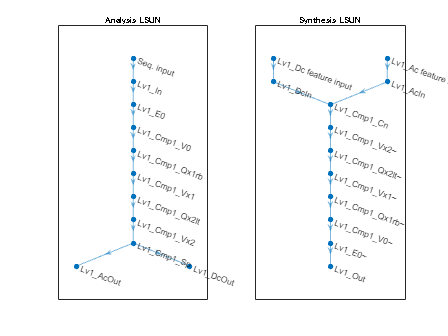

import tansacnet.lsun.*
analysislgraph = fcn_createcslsunlgraph1d([],...
 'InputSize',nX,...
 'Stride',stride,...
 'OverlappingFactor',kx,...
 'Mode','Analyzer');
synthesislgraph = fcn_createcslsunlgraph1d([],...
 'InputSize',nX,...
 'Stride',stride,...
 'OverlappingFactor',kx,...
 'Mode','Synthesizer');
figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis LSUN')

**Initialisation of design parameters**

% Standard deviation of initial angles
stdInitAng = 1e-9;
% Construction of synthesis network.
analysisnet = dlnetwork(analysislgraph);
% Initialize
nLearnables = height(analysisnet.Learnables);
expanalyzer = '^Lv\d+_Cmp\d+_Q(\w\d|0)+(\w)+$';
nLayers = height(analysislgraph.Layers);
for iLearnable = 1:nLearnables
     if analysisnet.Learnables.Parameter(iLearnable)=="Angles"
         alayerName = analysisnet.Learnables.Layer(iLearnable);
         if ~isempty(regexp(alayerName,expanalyzer,'once'))
         disp("Angles in " + alayerName + " are set to N(-pi/2,"+num2str(stdInitAng^2)+")")
         analysisnet.Learnables.Value(iLearnable) = ...
         cellfun(@(x) x+stdInitAng*randn(size(x))-pi/2, ...
         analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
         else
         disp("Angles in " + alayerName + " are set to N(0,"+num2str(stdInitAng^2)+")")
         analysisnet.Learnables.Value(iLearnable) = ...
         cellfun(@(x) x+stdInitAng*randn(size(x)), ...
         analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
         end
     end
end

Angles in Lv1_Cmp1_V0 are set to N(0,1e-18)


Angles in Lv1_Cmp1_Qx1rb are set to N(-pi/2,1e-18)


Angles in Lv1_Cmp1_Vx1 are set to N(0,1e-18)


Angles in Lv1_Cmp1_Qx2lt are set to N(-pi/2,1e-18)


Angles in Lv1_Cmp1_Vx2 are set to N(0,1e-18)


**Establishment of concomitant relationships**

**Copying design parameters**

import tansacnet.lsun.*
% Construction of analysis network
analysislgraph = layerGraph(analysisnet);
synthesislgraph = fcn_cpparamsana2syn(synthesislgraph,analysislgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vx1 to Lv1_Cmp1_Vx1~
Copy angles from Lv1_Cmp1_Vx2 to Lv1_Cmp1_Vx2~


synthesislgraph = fcn_cpparamsana2syn_csax_(synthesislgraph,analysislgraph);

Copy angles from Lv1_Cmp1_Qx1rb to Lv1_Cmp1_Qx1rb~
Copy angles from Lv1_Cmp1_Qx2lt to Lv1_Cmp1_Qx2lt~


synthesisnet = dlnetwork(synthesislgraph);

**Confirmation of the adjoint relationship (complete reconstruction).**

x = rand([1 nX 1 nT],'double');
dlx = dlarray(x,"SSCB"); % Deep learning array (SSCB)
[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
mse_ = mse(dlx,dly);
display("MSE: " + num2str(mse_))

    "MSE: 4.1947e-14"



assert(mse_<1e-6)

**Design parameter optimisation and signal approximation.**

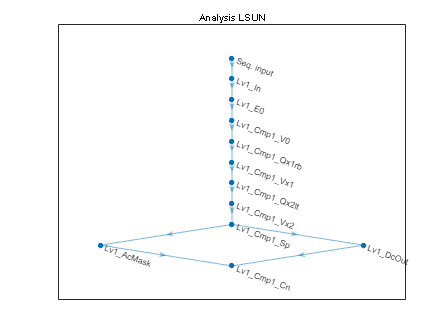

import tansacnet.lsun.*
analysislgraph = layerGraph(analysisnet);
% Coefficient masking
nChsTotal = prod(stride);
coefMask = reshape([ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)],2,[]).';
coefMask = coefMask(:);
%nLevels = 1;
%for iLv = nLevels:-1:1
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
analysislgraph = analysislgraph.replaceLayer([strLv 'AcOut'],...
 mask1dLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
 'NumberOfChannels',nChsTotal-1));
%strLvPre = strLv;
%end
% Output layer
iCmp = 1;
strCmp = sprintf('Cmp%0d_',iCmp);
%analysislgraph = analysislgraph.addLayers([...
% lsunChannelConcatenation1dLayer('Name',[strLv strCmp 'Cn']) ...
% lsunRegressionLayer('Coefficient output')
% ]);
analysislgraph = analysislgraph.addLayers(...
 lsunChannelConcatenation1dLayer('Name',[strLv strCmp 'Cn']));
analysislgraph = analysislgraph.connectLayers(...
 [strLv 'AcMask' ], [strLv strCmp 'Cn/ac']);
analysislgraph = analysislgraph.connectLayers(...
 [strLv 'DcOut' ], [strLv strCmp 'Cn/dc']);
figure
plot(analysislgraph)
title('Analysis LSUN')

**Reads numerical sequence data as 1-D images from a datastore.**

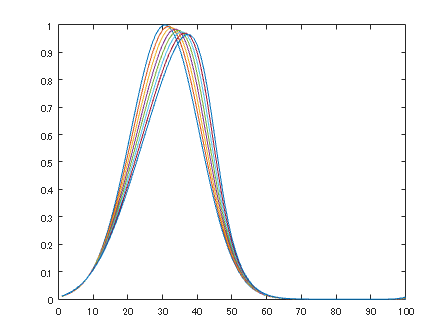

% Load sequences
arrds = arrayDatastore(DataT,"ReadSize",1,"IterationDimension",1);
%arrds = transform(arrds,@(x) cell2mat(x));
figure
arr = cell2mat(preview(arrds));
for idx = 1:height(arr)
 plot(arr(idx,:))
 hold on
end
hold off

**Design preparation**

dlX = dlarray(gpuArray(arr(1,:)),"SSCB");
trainnet = dlnetwork(analysislgraph,dlX);
assert(trainnet.Initialized)
figure
monitor = trainingProgressMonitor(Metrics="Loss",Info="Epoch",XLabel="Iteration");

**Optimisation design**

**Parameters for learning**

- Creating mini-batches for deep learning - MATLAB - MathWorks United Kingdom

numEpochs = 100; 
miniBatchSize = nT;
numObservationsTrain = nT;
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;
% Minibatch
mbq = minibatchqueue(arrds,...
 "MinibatchSize",miniBatchSize,...
 "MiniBatchFcn",@(x) permute(cell2mat(x),[3 2 4 1]),...
 "OutputAsDlarray",1,...
 ..."OutputCast","double",...
 "MiniBatchFormat", "SSCB",...
 "OutputEnvironment", "gpu",...
 "PartialMiniBatch","discard");
% Training
averageGrad = [];
averageSqGrad = [];
iteration = 0;
epoch = 0;
start = tic;
% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
     epoch = epoch + 1;
     % Shuffle data.
     shuffle(mbq);
     % Loop over mini-batches.
     while hasdata(mbq) && ~monitor.Stop
     iteration = iteration + 1;
     % Read mini-batch of data.
     dlX = next(mbq);
     % Evaluate the model gradients, state, and loss using dlfeval and the
     % modelGradients function and update the network state.
    [loss,grad] = dlfeval(@modelLoss,trainnet,dlX);
     %Update the network parameters using the Adam optimizer.
     [trainnet,averageGrad,averageSqGrad] = ...
     adamupdate(trainnet,grad,averageGrad,averageSqGrad,iteration);
     % Display the training progress.
     recordMetrics(monitor,iteration,Loss=loss);
     updateInfo(monitor,Epoch=epoch + " of " + numEpochs);
     monitor.Progress = 100 * iteration/numIterations;
     end
end

### Trained Analysis LSUN

import tansacnet.lsun.*
analsunlgraph = fcn_createcslsunlgraph1d([],...
    'InputSize',nX,...
    'Stride',stride,...
    'OverlappingFactor',kx,...
    ...'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
synlsunlgraph = fcn_createcslsunlgraph1d([],...
    'InputSize',nX,...
    'Stride',stride,...
    'OverlappingFactor',kx,...
    ...'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
trainlgraph = layerGraph(trainnet);
% Trained net -> Analyzer
synlsunlgraph = fcn_cpparamsana2syn(synlsunlgraph,trainlgraph);
synlsunlgraph = fcn_cpparamsana2syn_csax_(synlsunlgraph,trainlgraph); 
% Analyzer -> Synthesizer
analsunlgraph = fcn_cpparamssyn2ana(analsunlgraph,synlsunlgraph);
analsunlgraph = fcn_cpparamssyn2ana_csax_(analsunlgraph,synlsunlgraph); 

nLevels = 1;
%for iLv = nLevels:-1:1S
iLv = 1;

% !!! 完全再構成を確認するためマスク処理を無効化
% coefMask = ones(nChsTotal,1);

strLv = sprintf('Lv%0d_',iLv);
% For analyzer
analsunlgraph = analsunlgraph.replaceLayer([strLv 'DcOut'],...
    regressionLayer('Name',[strLv 'DcOut']));
%analsunlgraph = analsunlgraph.addLayers(...
%    mask1dLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
%    'NumberOfChannels',nChsTotal-1));
%analsunlgraph = analsunlgraph.connectLayers([strLv 'AcOut'],[strLv 'AcMask']);
analsunlgraph = analsunlgraph.replaceLayer([strLv 'AcOut'], ...
        mask1dLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
analsunlgraph = analsunlgraph.addLayers(regressionLayer('Name',[strLv 'AcOut']));
analsunlgraph = analsunlgraph.connectLayers([strLv 'AcMask'],[strLv 'AcOut']);

% For synthesizer
synlsunlgraph = synlsunlgraph.replaceLayer([strLv 'Out'],...
    regressionLayer('Name',[strLv 'Out']));
%
synlsunlgraph = synlsunlgraph.disconnectLayers([strLv 'Ac feature input'],[strLv 'AcIn']);
synlsunlgraph = synlsunlgraph.addLayers(...
    mask1dLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
synlsunlgraph = synlsunlgraph.connectLayers([strLv 'Ac feature input'],[strLv 'AcMask']);
synlsunlgraph = synlsunlgraph.connectLayers([strLv 'AcMask'],[strLv 'AcIn']);

%strLvPre = strLv;
%end

%
figure
subplot(1,2,1)
plot(analsunlgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synlsunlgraph)
title('Synthesis LSUN')
% Replace invalid linear layers with empty lattice parameters
fcn_replace_emptyangles_(analsunlgraph)
fcn_replace_emptyangles_(synlsunlgraph)


analsunlgraph.Layers
synlsunlgraph.Layers


analsunnet = assembleNetwork(analsunlgraph)
synlsunnet = assembleNetwork(synlsunlgraph)

### Analysis process

analsunseq = zeros(nT,stride,ndim/stride,'like',DataT);
for iT = 1:nT
    [dc,ac] = analsunnet.predict(gpuArray(DataT(iT,:))); % dc: 1 x Pos., ac: Ch. x 1 x Pos
    analsunseq(iT,:,:) = cat(2,permute(dc,[3 1 2]),permute(ac,[2 1 3]));
end
% 3-D array w/ Time x Ch. x Pos.
size(analsunseq)

### Synthesis process

synlsunnet.Layers(11).InputSize
synlsunnet.Layers(12).InputSize
synlsunseq = analsunseq;
DataTaprx = zeros(size(DataT),'like',DataT);
for iT = 1:nT
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

figure
disp_plot3_(T,X,DataTaprx)
figure
disp_imagesc_(T,X,DataTaprx)
% MSE評価
mse(DataT,DataTaprx)

### td-DMD


nRange = size(analsunseq,1); 

size(analsunseq) % K x Ch. x Pos.
matS = eye(stride);
matS = matS(coefMask==1,:)
dataY = pagemtimes(matS, permute(analsunseq,[2 1 3])); % Ch. x K x Pos.
dataX = reshape(ipermute(dataY,[2 1 3]),nRange,[]) % K x (Ch.Pos.)

% !!! By YASAS

% Construction of Hankel matrix
%{
analsunseq_ = permute(analsunseq,[2,3,1]);
dcac_ = zeros(1,size(analsunseq_,2)*2,100);
for i = 0:size(analsunseq_,2)-1
    dcac_(1,(i*2)+1,:) = analsunseq_(1,i+1,:);
    dcac_(1,(i*2)+2,:) = analsunseq_(3,i+1,:);
end
x = squeeze(dcac_).';
%x = reshape(dcac_,[size(analsunseq_,2)*2,100]).';
%}


% Construction of Hankel matrix
x = dataX;

ts = [];
H = [];
%nRange = size(x,1)-1;
nRange = size(x,1);
for k = 0:nRange-nDelay-1
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,x(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end
H

Step 2 SVD of H

[U,Sgm,V] = svd(H,'econ')

Step 3 PCT

iMode = 1
ui = reshape(U(:,iMode),size(x,2),[]).'

Visualize

%myplot(T(1:size(ui,1)),ui)

V0 = V(1:end-1,:);
V1 = V(2:end,:);
dtAplusI = (V1.')*pinv(V0.') 

Step 4 Discover forcinge signal

v0hat = V(1,:).';
vk = v0hat;
dtrk_ = 0;
dtr = [];
for k = 1:nRange-nDelay-1
    % True value
    vkp1 = V(k+1,:).';
    % Forcasted value
    vkp1hat = dtAplusI*vk;
    % Forcing signal
    dtrk_ = vkp1 - vkp1hat;
    % Update
    vk = vkp1;
    dtr = cat(2,dtr,dtrk_);
end

Learnable parameters

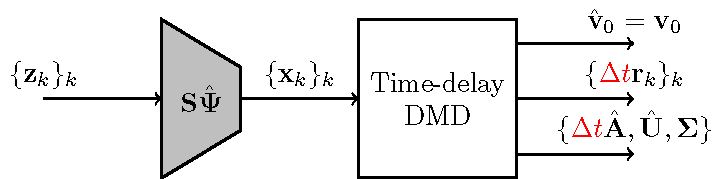

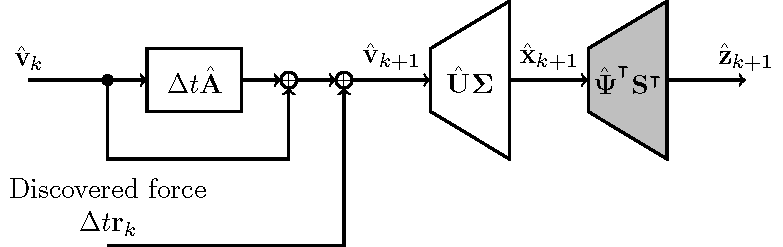

Parameters


$$\hat{\mathbf{v}}_0$$


v0hat


$$\{\Delta t \mathbf{r}_k\}$$


dtr


$$\mathbf{I}+\Delta t \hat{\mathbf{A}}$$


dtAplusI


$$\hat{\mathbf{U}}$$


rRed = nCoefs/stride;
Uhat = U(1:(ndim*rRed),:);
Uhat


$$\mathbf{\Sigma}$$


Sgm

Step 5 w/ Discovered forcing signal

vkhat = v0hat;
%dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat + dtrk;
    Xhat =  cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

% Reshape results
size(Xhat)  % (K-D) x (Ch.Pos.)
nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Xhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataXhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataXhat)


% Reconstruction of output to be sent throughr LSUN synthesizer
synlsunseq = dataXhat;
DataHatTaprx = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataHatTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

figure
disp_imagesc_(T,X,DataHatTaprx)
% MSE評価
mse(DataT(1:nRangeOut,:),DataHatTaprx)

Step 6 w/o Discovered forcing signal

vkhat = v0hat;
%dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay-1
    %dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat;
    Xhat =  cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

% Reshape results
size(Xhat)  % (K-D) x (Ch.Pos.)
nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Xhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataXhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataXhat)


% Reconstruction of output to be sent throughr LSUN synthesizer
synlsunseq = dataXhat;
DataHatTaprx = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataHatTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

figure
disp_imagesc_(T,X,DataHatTaprx)
% MSE評価
mse(DataT(1:nRangeOut,:),DataHatTaprx)

**Function definition.**

Peter Mao (2023). fftfreq(https://www.mathworks.com/matlabcentral/fileexchange/67026-fftfreq), MATLAB Central file exchange. Retrieved, 6 January 2023.

function f=fftfreq(npts,dt,alias_dt)
% returns a vector of the frequencies corresponding to the length
% of the signal and the time step.
% specifying alias_dt > dt returns the frequencies that would
% result from subsampling the raw signal at alias_dt rather than
% dt.
 
 
 if (nargin < 3)
 alias_dt = dt;
 end
 fmin = -1/(2*dt);
 df = 1/(npts*dt);
 f0 = -fmin;
 alias_fmin = -1/(2*alias_dt);
 f0a = -alias_fmin;
 
 ff = mod(linspace(0, 2*f0-df, npts)+f0, 2*f0) - f0;
 fa = mod( ff+f0a, 2*f0a) - f0a;
 % return the aliased frequencies
 f = fa;
end


Definition of ODE system (PDE ---(FFT)---> ODE system)

%Definition of ODE system (PDE ---(FFT)---> ODE system)
function u_t_real = burg_system(u, t, k,mu,nu)
 %Spatial derivative in the Fourier domain
 u_hat = fft(u);
 u_hat_x = 1j*k(:).*u_hat;
 u_hat_xx = -(k(:).^2).*u_hat;
 
 %Switching in the spatial domain
 u_x = ifft(u_hat_x);
 u_xx = ifft(u_hat_xx);
 
 %ODE resolution
 u_t = -mu*u.*u_x + nu*u_xx;
 u_t_real = real(u_t);
end

Function to extract a local patch block from a global array

function y = fcn_extract_blks_(x,iBlk,blksz,kx)
% Extend array x
padsz = [0 (kx-1)*blksz/2];
xx = padarray(x,padsz,"circular");
%
posx = (iBlk-1)*blksz+1;
y = xx(:,posx:posx+kx*blksz-1);
end

Function to place a local patch block to a global array

function y = fcn_place_blks_(y,blk,iBlk,blksz)
% Extend array x
posx = (iBlk-1)*blksz+1;
y(:,posx:posx+blksz-1) = blk;
end

Loss function

where is a unitaly analyzer with a coefficient mask. is guaranteed.

function [loss,gradients] = modelLoss(dlnet, dlX)
% Forward data through the dlnetwork object.
dlY = forward(dlnet,dlX); % F(x)
% Compute loss.
Nx = size(dlX,4);
Ny = size(dlY,4);
loss = sum(dlX.^2,"all")/Nx-sum(dlY.^2,"all")/Ny;
% Compute gradients.
gradients = dlgradient(loss,dlnet.Learnables);
loss = double(gather(extractdata(loss)));
end

function disp_plot3_(T,X,DataT,c)
if nargin < 4
 c = 'blue';
end
for idx = 1:length(X)
 plot3(X,T(idx)*ones(size(X)),DataT(idx,:),...
 'Color',c,...
 'LineWidth',1)
 hold on
end
xlabel('$x$', 'FontSize',14,'Interpreter','latex')
ylabel('$t$', 'FontSize',14,'Interpreter','latex')
zlabel('$u$', 'FontSize',14,'Interpreter','latex')
ax = gca;
ax.View = [30 30];
ax.PlotBoxAspectRatio = [ 1 1 1];
grid on
hold off
end

function disp_imagesc_(T,X,DataT)
imagesc(DataT)
colormap("jet")
colorbar
title('Burgers Equation','FontSize',15)
xlabel('Spatial','FontSize',12)
ylabel('Time','FontSize',12)
ax = gca;
ax.PlotBoxAspectRatio = [1 1 1];
ax.XTick = 1:20:100;
ax.XTickLabel = round(X(ax.XTick));
ax.YTick = 1:20:100;
ax.YTickLabel = round(T(ax.YTick));
end

function disp_plotmv_(ax,T,X,DataT,AprxT)
     a = DataT(1,:);
     b = AprxT(1,:);
     p = plot(ax,X,a,X,b);
     axis([min(X) max(X) min(DataT(:)) max(DataT(:))])
     xlabel('x')
     grid on
     hold on
     drawnow
     for iT = 2:length(T)
     a = DataT(iT,:);
     b = AprxT(iT,:);
     p(1).YData = a;
     p(2).YData = b;
     drawnow
     end
     hold off
end

function synthesislgraph = fcn_cpparamsana2syn_csax_(synthesislgraph,analysislgraph)
expanalyzer = '^Lv\d+_Cmp\d+_Q(\w\d|0)+(\w)+$';
nLayers = height(analysislgraph.Layers);
for iLayer = 1:nLayers
     alayer = analysislgraph.Layers(iLayer);
     alayerName = alayer.Name;
         if ~isempty(regexp(alayerName,expanalyzer,'once'))
         slayer = synthesislgraph.Layers({synthesislgraph.Layers.Name} == alayerName + "~");
         slayer.Angles = alayer.Angles;
         synthesislgraph = synthesislgraph.replaceLayer(slayer.Name,slayer);
         disp("Copy angles from " + alayerName + " to " + slayer.Name)
         end
end
end

function analysislgraph = fcn_cpparamssyn2ana_csax_(analysislgraph,synthesislgraph)
expanalyzer = '^Lv\d+_Cmp\d+_Q(\w\d|0)+(\w)+$';
nLayers = height(analysislgraph.Layers);
for iLayer = 1:nLayers
 alayer = analysislgraph.Layers(iLayer);
 alayerName = alayer.Name;
     if ~isempty(regexp(alayerName,expanalyzer,'once'))
     slayer = synthesislgraph.Layers({synthesislgraph.Layers.Name} == alayerName + "~");
     alayer.Angles = slayer.Angles;
     analysislgraph = analysislgraph.replaceLayer(alayerName,alayer);
     disp("Copy angles from " + slayer.Name + " to " + alayerName)
     end
end
end

function myplot(t,x)

subplot(1,2,1)
plot(t,[x(:,1)+15 x(:,2)-5 x(:,3)-45]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'x3','x2','x1'})
xlabel('t')
title('Burgers Eq')

subplot(1,2,2)
plot3(x(:,1),x(:,2),x(:,3));
xlabel('x1')
ylabel('x2')
zlabel('x3')

end


function fcn_replace_emptyangles_(lsunlgraph)
explayer = '^Lv\d+_Cmp\d+_V(\w\d|0)+(~|)$';
nLayers = height(lsunlgraph.Layers);
for iLayer = 1:nLayers
    layer_ = lsunlgraph.Layers(iLayer);
    if ~isempty(regexp(layer_.Name,explayer,'once'))
        if isa(layer_,"tansacnet.lsun.lsunIntermediateFullRotation1dLayer") && isempty(layer_.Angles)
            newlayer = tansacnet.lsun.lsunSign1dLayer( ...
                'Name',layer_.Name, ...
                'Stride',layer_.Stride, ...
                'Mode',layer_.Mode, ...
                'NumberOfBlocks',layer_.NumberOfBlocks, ...
                'Mus',layer_.Mus);
            lsunlgraph = lsunlgraph.replaceLayer(layer_.Name,newlayer);
            display("Replaced " + layer_.Name + " to " + class(newlayer))
        end
    end
end
end